scores = 1×126 cell array
    {[1.1558e+03 1.1375e+03 1.1304e+03 1.1389e+03 1.1386e+03 1.1229e+03 1.1147e+03 1.1137e+03 1.1093e+03 1.1112e+03 1.1145e+03 1.1101e+03 1.1099e+03 1.1167e+03 1.1153e+03 1.1078e+03 1.1160e+03 1.1074e+03 1.1167e+03 1.1177e+03 1.1041e+03 1.1050e+03 … ]}    {[1.1548e+03 1.1537e+03 1.1528e+03 1.1516e+03 1.1558e+03 1.1544e+03 1.1625e+03 1.1534e+03 1.1515e+03 1.1618e+03 1.1639e+03 1.1566e+03 1.1638e+03 1.1880e+03 1.1569e+03 1.1429e+03 1.1565e+03 1.1502e+03 1.1491e+03 1.1413e+03 1.1440e+03 1.1395e+03 … ]}    {[1.1761e+03 1.1655e+03 1.1746e+03 1.1763e+03 1.1628e+03 1.1552e+03 1.1599e+03 1.1532e+03 1.1537e+03 1.1362e+03 1.1370e+03 1.1487e+03 1.1497e+03 1.1511e+03 1.1383e+03 1.1472e+03 1.1816e+03 1.1695e+03 1.1502e+03 1.1484e+03 1.1491e+03 1.1452e+03 … ]}    {[1.1642e+03 1.1501e+03 1.1445e+03 1.1347e+03 1.1426e+03 1.1333e+03 1.1305e+03 1.1264e+03 1.1316e+03 1.1361e+03 1.1437e+03 1.1436e+03 1.1620e+03 1.1410e+03 1.1470e+03 1.1416e+03 1.1392e+03 1.1507e+03 1.1531e+03]}  

Error using min
Invalid data type. First argument must be numeric or logical.

Error in fill_the_cluster (line 16)
vmin = min(scores);

cluster_num = 126

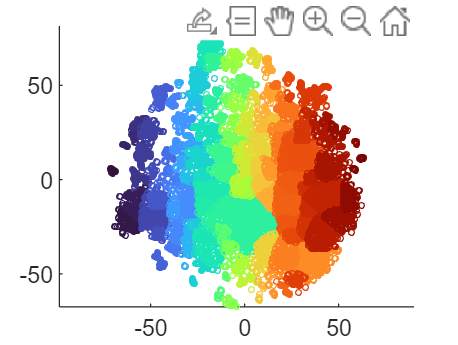

load("_test_folder\34A_D1_G8m_permutated.mat");

load("_test_folder\analysisstruct_concat.mat");

signal = data.channel_470;

membership = analysisstruct_concat.annot_reordered{end,end};
clusterIDs = analysisstruct_concat.sorted_clust_ind(:);
pts = analysisstruct_concat.zValues(membership==clusterIDs(1),:);    % z-values for cluster k
frame_idx = analysisstruct_concat.frames_with_good_tracking(1);


% 
channel = 1;

cluster_scores = gather_channel_values(clustered_v, channel);

% get the signal_mean of each cluster
scores = cellfun(@mean, cluster_scores)

scores = 1.0e+03 *

    1.1169    1.1414    1.1445    1.1429    1.1298    1.1245    1.1418    1.1393    1.1479    1.1593    1.1243    1.2083    1.1490    1.1048    1.0931    1.1230    1.1141    1.1426    1.1384    1.1257    1.1102    1.1566    1.1462    1.1303    1.1302    1.1435    1.1124    1.1211    1.1217    1.1314    1.1481    1.1268    1.1365    1.1375    1.1495    1.1210    1.1560    1.1251    1.1567    1.1376    1.1133    1.1205    1.1530    1.1444    1.1520    1.1415    1.1614    1.1161    1.1288    1.1366


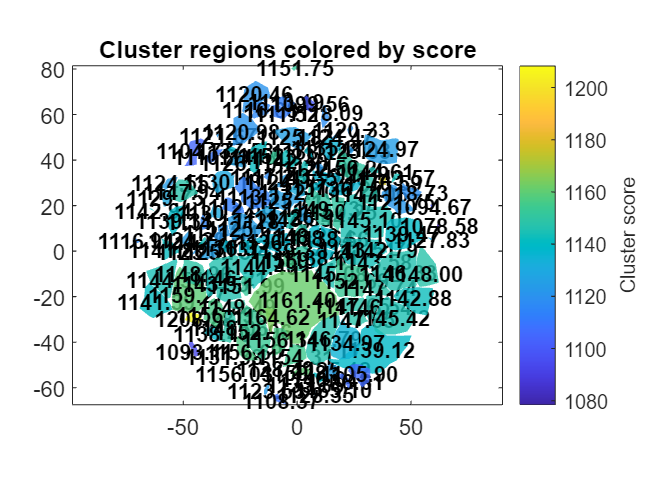


fill_the_cluster(clustered_z, scores)

cluster_num = numel(clustered_z)
cmap        = turbo(cluster_num);

figure; hold on
for i = 1:cluster_num
    z_values_in_cluster = clustered_z{i};
    scatter(z_values_in_cluster(:, 1), z_values_in_cluster(:, 2), 5, cmap(i,:));
end
axis equal


% get all the signal segments and plot them together
